**Multiband ADMM-based compressed sensing demo with improved adaptive parameters**

This version includes enhanced adaptive rho logic 

## 1. Initialization

Assumptions:

- Time-invariant channel (Hchan)

- Frequency-**dependent** RCS (channel gains)

- Noise variance constant across all frequencies

%% 1. Initialization
clc
clear all;
close all;
rng(57);

addpath('/Users/lanthanum457/Desktop/NYUAD/PhD/Research/2. Compressed Sensing (Wireless Course Project)/Code')

% Constants
c = physconst('lightspeed');
colors = [043 048 122;
          119 194 243;
          247 238 246;
          216 160 199;
          169 111 176]/255;           % Colors for visualization

% System Parameters
MB_f = [12 18 22]*1e9;          % Subband frequencies
Q = 1000;                       % Number of subcarriers
MB_fb = [120 180 220] * 1e3;    % Subcarrier spacing
MB_d = (c./MB_f)./2;            % Antenna spacing
M = 60;                         % Number of antennas
K = length(MB_f);               % Number of subbands
modulation = 4;                 % 4-QAM
PT = 0;                         % Transmit power (dBm)
N0 = -174;                     % Thermal noise power spectral density (dBm)
NF = 7;                         % Noise figure (dB)

% Path parameters
npaths = 12;
gains = rand(npaths,K) + 1i * rand(npaths,K);           % DEPENDENT on subband frequency
delays = round((40 + rand(npaths,1) * 160)) * 1e-9;     % ON-GRID delays between 40 and 200 ns (limit to farfield)
angles = round(rand(npaths,1) * 180 - 90);              % ON-GRID angles between -90 and 90 deg
% npaths = 3;
% gains = ones(npaths,K);
% delays = [150 100 50].' * 1e-9;
% angles = [-45 0 45].';
PL = 1./(4*pi*MB_f.*delays).^2;                         % Pathloss

% ADMM Parameters
max_iter = 1000;                    % Max ADMM iterations
rho_init = 1;                       % Initial ADMM penalty parameter
alpha = 1;                          % Step size scaling
tol_abs = 1e-8;                     % Absolute tolerance
tol_rel = 1e-8;                     % Relative tolerance
anglegrid_cs = (-90:1:90).';        % Angle grid
delaygrid_cs = (0:1:200).'*1e-9;    % Delay grid
L_angle = length(anglegrid_cs);
L_delay = length(delaygrid_cs);


- `rv_epsilon`: Relative threshold for detecting significant noise variance increase

- `rb_epsilon`: Relative threshold for detecting stable noise variance

- `mu_rho`: Balance factor for primal and dual residuals (used in adaptive rho)

- `tau_incr`, `tau_decr`: Scaling factors for increasing/decreasing rho

- `rho_check_interval`: Number of iterations between rho updates

- `rho_min`, `rho_max`: Bounds to prevent rho from becoming too small or too large

- `epsilon_scale_factor`: Three different scaling factors for epsilon updates

% Adaptive parameter constants
mu_incr = 1000;                         % Balance factor for primal and dual residuals
mu_decr = 0.001;
tau_incr = 1/0.98;                     % Rho increase factor
tau_decr = 0.98;                     % Rho decrease factor
rho_check_interval = 1;            % Check residual balance every N iterations
rho_min = 1e-5;                     % Minimum allowed rho value
rho_max = 1e5;                       % Maximum allowed rho value

Note:

- delay resolution ~ 1/bandwidth

- angle resolution (HPBW) ~ 180*lambda/(pi*d*(M-1))

% Display bandwidth info
BW = Q.*MB_fb;
disp(['Bandwidth: [',num2str(BW/1e6),'] MHz']);    % Display bandwidth

Bandwidth: [120  180  220] MHz


**2. Channel and Signal Generation**

%% 2. Channel and Signal Generation
% Initialize Variables
s = cell(K,1);                              % Pilot symbols
Y = cell(K,1);                              % Received signal
snr = zeros(K,1);                           % SNR of Received signal
A1 = cell(K,1);                             % Delay Dictionary
A2 = cell(K,1);                             % Angle Dictionary
norm_A_full = zeros(K,1);                   % Matrix L2-norm used in calculating step size
A_norms = cell(K,1);                        % Store norms for each subband dictionary

% Noise Variance
noisevar_total = db2pow(N0+NF) * sum(BW);   % Total noise variance (mW)
noisevar = db2pow(N0+NF) * BW;              % Noise variance per subband (mW)

for k = 1:K
    fb = MB_fb(k);
    d = MB_d(k);
    f = MB_f(k);

    % Channel Matrix (Hchan)
    Hchan = zeros(M,Q);
    for p = 1:npaths
        a_R = exp(-1i*2*pi*d*f*(0:M-1).'*sind(angles(p))/c); % Rx steering
        a_F = exp(-1i*2*pi*(f+fb*(0:Q-1).')*delays(p)); % Freq steering
        Hchan = Hchan + sqrt(db2pow(PT))*sqrt(PL(p,k)).*gains(p,k).* (a_R*a_F.'); % Outer product
    end

    % Pilot symbols (s)
    s{k} = qammod(randi([0,modulation-1],Q,1),modulation,'UnitAveragePower',true);

    % Received signal (Y)
    W = sqrt(noisevar(k)/2) * (randn(M,Q) + 1i * randn(M,Q));
    Y{k} = Hchan.*s{k}.' + W;
end

We can see that the channel is quite **frequency-selective (has a much smaller coherence bandwidth) within our system bandwidth** for all subbands!

% Calculate and Display initial SNR
for k = 1:K
    snr(k) = pow2db(mean(abs(Y{k}).^2,'all') / noisevar(k));
    disp([num2str(MB_f(k)/1e9),' GHz', ...
        ' - SNR: ',num2str(snr(k)),' dB']);
end

12 GHz - SNR: 41.3895 dB
18 GHz - SNR: 35.8477 dB
22 GHz - SNR: 32.2448 dB


We can see that with increasing pathloss at higher subband frequencies, the effective SNR decreases. 

**3. Compressed Sensing ADMM Solver**

% Compute Dictonaries
for k = 1:K
    fb = MB_fb(k);
    d = MB_d(k);
    f = MB_f(k);
    % Delay Dictionary (A1)
    A1{k} = zeros(Q, L_delay);
    for i = 1:L_delay
        A1{k}(:,i) = s{k} .* exp(-1i*2*pi*(f+fb*(0:Q-1).')*delaygrid_cs(i));
    end

    % Angle Dictionary (A2)
    A2{k} = zeros(M, L_angle);
    for i = 1:L_angle
        A2{k}(:,i) = exp(-1i*2*pi*d*(0:M-1).'*f*sind(anglegrid_cs(i))/c);
    end

    % Calculate matrix norms for step size calculation
    norm_A2 = norm(A2{k}, 2);
    norm_A1 = norm(A1{k}, 2);
    norm_A_full(k) = norm_A1 * norm_A2;
    A_norms{k} = [norm_A1, norm_A2];
end

% Initialize constraint bound using actual noise variance
epsilon_total = 1.2*sqrt(M*Q*noisevar_total);           % Initial constraint bound
epsilon = epsilon_total.*sqrt(BW./sum(BW));             % Per-subband constraint

- `rho`: Vector of penalty parameters for each subband

- `reslog`: Matrix to store residual history for plotting

- `sigma_sq_last`, `sigma_sq`: Noise variance estimates

% Initialize variables
HH = zeros(L_delay*L_angle, K);    % Matrix to optimize
Z = cell(K,1);                      % Auxiliary variables
U = cell(K,1);                      % Dual variables
%rho = rho_init;         % Penalty parameter
rho = rho_init * ones(K,1);         % Penalty parameter
reslog = [];                        % Diagnostic residual history
sigma_sq_last = noisevar;           % Initialize using true noise variance
sigma_sq = noisevar;                % Current noise estimate

Gamma calculates the step size for each subband based on: 

- `alpha`: Scaling factor

- `rho`: Penalty parameter

- `norm_A_full^2`: Squared norm of the full dictionary

% Initialize gamma (step size) for each subband
gamma = alpha / max(rho.*norm_A_full.^2,[],'all');

% Initialize Z and U
for k = 1:K
    Z{k} = zeros(M,Q);    % Initialize Z_k
    U{k} = zeros(M,Q);    % Initialize U_k
end

Creates arrays to track performance metrics over iterations: 

- `pres_history`: Primal residuals

- `dres_history`: Dual residuals

- `epsilon_history`: Epsilon values

- `rho_history`: Rho values

- `sigma_sq_history`: Noise variance estimates

% Performance tracking
pres_history = zeros(max_iter, K);
dres_history = zeros(max_iter, K);
epsilon_history = zeros(max_iter, K);
rho_history = zeros(max_iter, K);
sigma_sq_history = zeros(max_iter, K);

% ADMM iterations
for iter = 1:max_iter
    % For checking convergence
    Z_prev = Z;
    primal_res = zeros(K,1);
    dual_res = zeros(K,1);

    % Update HH using proximal gradient step
    G = zeros(size(HH));
    for k = 1:K
        % Compute A_full,k * h_k efficiently
        h_k = HH(:,k);
        h_k_mat = reshape(h_k, [L_angle, L_delay]);
        AhA = A2{k} * h_k_mat * A1{k}.';

        % Gradient computation
        res_mat = AhA - (Z{k} - U{k});
        grad_mat = A2{k}' * res_mat * conj(A1{k}); % A1 is conjugated in dictionary
        %G(:,k) = rho * grad_mat(:);
       G(:,k) = rho(k) * grad_mat(:);
    end

    HH_temp = HH - gamma * G;

    % Apply proximal operator (row-wise group soft-thresholding)
    rownorms = vecnorm(HH_temp, 2, 2);
    HH = max(0,1 - gamma./rownorms) .* HH_temp;

    % Update Z (auxiliary variables) with ADMM projection step
    for k = 1:K
        % Reshape HH to matrix form for efficient computation
        h_k_mat = reshape(HH(:,k), [L_angle, L_delay]);
        AhA = A2{k} * h_k_mat * A1{k}.';

        % Update Z with proximal operator (projection onto l2 ball)
        Z_tilde = AhA + U{k};
        Y_k = Y{k};

        % Calculate residual
        R = Z_tilde - Y_k;
        R_norm = norm(R, 'fro');

        % Projection onto epsilon-radius ball
        if R_norm > epsilon(k)
            Z{k} = Y_k + epsilon(k) * R / R_norm;
        else
            Z{k} = Z_tilde;
        end

        % Update residuals for convergence check
        primal_res(k) = norm(AhA - Z{k}, 'fro');
        %dual_res(k) = rho .* norm(Z{k} - Z_prev{k}, 'fro');
        dual_res(k) = rho(k) .* norm(Z{k} - Z_prev{k}, 'fro');
    end

    % Update dual variables U
    for k = 1:K
        h_k_mat = reshape(HH(:,k), [L_angle, L_delay]);
        AhA = A2{k} * h_k_mat * A1{k}.';
        U{k} = U{k} + (AhA - Z{k});
    end


    % Overall residuals for convergence
    primal_res_all = norm(primal_res,2);
    dual_res_all = norm(dual_res,2);

    % Adaptive rho update (every rho_check_interval iterations)
    if mod(iter, rho_check_interval) == 0

        % Balance primal and dual residuals
        % if primal_res_all > mu_incr * dual_res_all
        %     % Primal residual too large - increase penalty
        %     rho = min(rho_max, rho * tau_incr);
        %     U = cellfun(@(U) U/tau_incr,U,'UniformOutput', false); % rho and U update together
        % elseif dual_res_all > mu_decr * primal_res_all
        %     % Dual residual too large - decrease penalty
        %     rho = max(rho_min, rho * tau_decr);
        %     U = cellfun(@(U) U/tau_decr,U,'UniformOutput', false); %
        % end


        for k = 1:K
            if primal_res(k) > mu_incr * dual_res(k)
                % Primal residual too large - increase penalty
                 rho(k) = min(rho_max, rho(k) * tau_incr);
                 U{k} = U{k} / tau_incr;  % Rescale dual variable
                if mod(iter, 1) == 0 
                    epsilon(k) = 0.998 * epsilon(k); % prevent loose bound??
                end
            elseif dual_res(k) > mu_decr * primal_res(k)
                % Dual residual too large - decrease penalty
                 rho(k) = max(rho_min, rho(k) * tau_decr);
                 U{k} = U{k} / tau_decr;  % Rescale dual variable
                if mod(iter, 1) == 0
                    epsilon(k) = 1/0.998 * epsilon(k); % prevent overfit??
                end
            end
        end
        % Recompute step size gamma after rho update
        gamma = alpha / max(rho.*norm_A_full.^2,[],'all');
    end



Iteration 100, All-band Primal Res: 0.026666, All-band Dual Res: 4.6451e-05
Iteration 200, All-band Primal Res: 0.011773, All-band Dual Res: 1.1847e-05
Iteration 300, All-band Primal Res: 0.010192, All-band Dual Res: 1.0037e-05
Iteration 400, All-band Primal Res: 0.0081648, All-band Dual Res: 8.2976e-06
Iteration 500, All-band Primal Res: 0.0057849, All-band Dual Res: 5.7218e-06
Iteration 600, All-band Primal Res: 0.0043741, All-band Dual Res: 4.3762e-06
Iteration 700, All-band Primal Res: 0.0034483, All-band Dual Res: 3.4119e-06
Iteration 800, All-band Primal Res: 0.0030291, All-band Dual Res: 3.0452e-06
Iteration 900, All-band Primal Res: 0.0027584, All-band Dual Res: 2.7284e-06


Converged at iteration 923


Adaptive rho update logic (every `rho_check_interval` iterations): 

- If primal residual is much larger than dual: Increase rho

- If dual residual is much larger than primal: Decrease rho

- Keep rho within [rho_min, rho_max] range

- Rescale dual variables to maintain consistency

- Recompute step size gamma based on new rho

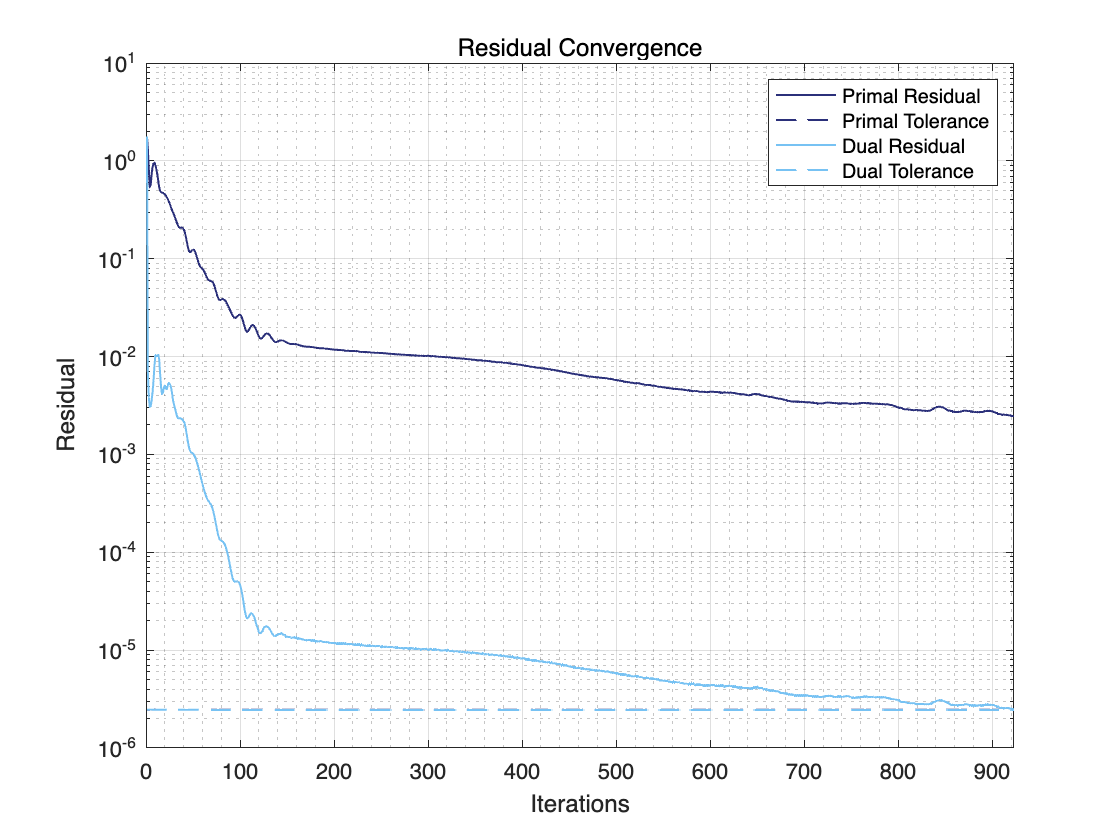

    % Log performance metrics
    pres_history(iter,:) = primal_res.';
    dres_history(iter,:) = dual_res.';
    epsilon_history(iter,:) = epsilon.';
    rho_history(iter,:) = rho.';
    sigma_sq_history(iter,:) = sigma_sq.';

    % Display progress
    if mod(iter, 100) == 0
        disp(['Iteration ', num2str(iter), ...
            ', All-band Primal Res: ', num2str(primal_res_all), ...
            ', All-band Dual Res: ', num2str(dual_res_all)]);
    end

    % Add termination criteria based on residuals
    % Primal tolerance

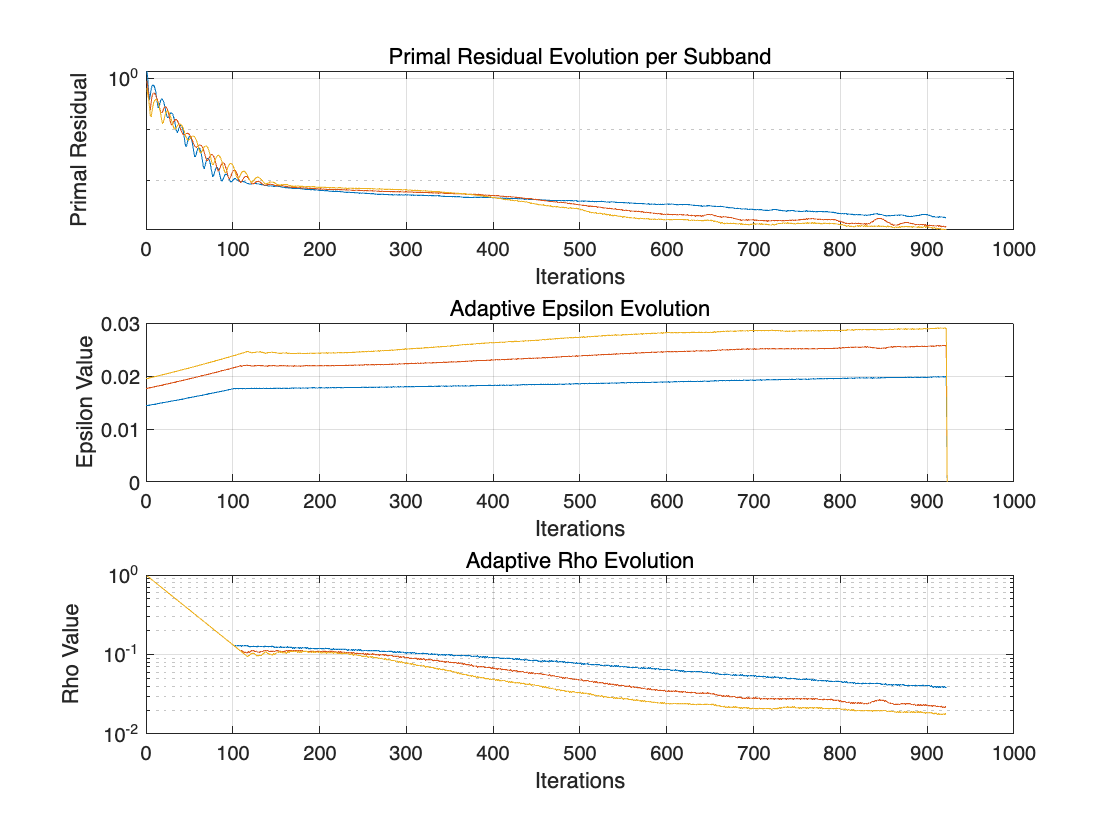

    max_norm_Z = max(cellfun(@(Z) norm(Z,'fro'), Z));
    max_norm_AhA = zeros(K,1);
    for k = 1:K
        h_k_mat = reshape(HH(:,k), [L_angle, L_delay]);
        AhA = A2{k} * h_k_mat * A1{k}.';
        max_norm_AhA(k) = norm(AhA, 'fro');
    end
    max_norm_AhA = max(max_norm_AhA);
    tol_primal = tol_abs * sqrt(M*Q) + tol_rel * max(max_norm_AhA, max_norm_Z);

    % Dual tolerance
    %max_norm_U = max(cellfun(@(U) norm(rho .* U,'fro'), U));
   max_norm_U = max(cellfun(@(U,rho) norm(rho .* U,'fro'), U,num2cell(rho)));
    tol_dual = tol_abs * sqrt(M*Q) + tol_rel * max_norm_U;

    % Diagnostic: Residual convergence
    reslog(iter,:) = [primal_res_all, tol_primal, dual_res_all, tol_dual];

    % Check termination
    if  dual_res_all < tol_dual %&& primal_res_all < 100*tol_primal
        disp(['Converged at iteration ', num2str(iter)]);
        break;
    end
end


% Average channel magnitude across subbands
Hestmag = reshape(mean(abs(HH),2), [L_angle, L_delay]);

- Plot residual convergence for diagnostics

- Shows primal and dual residuals vs. their respective tolerances

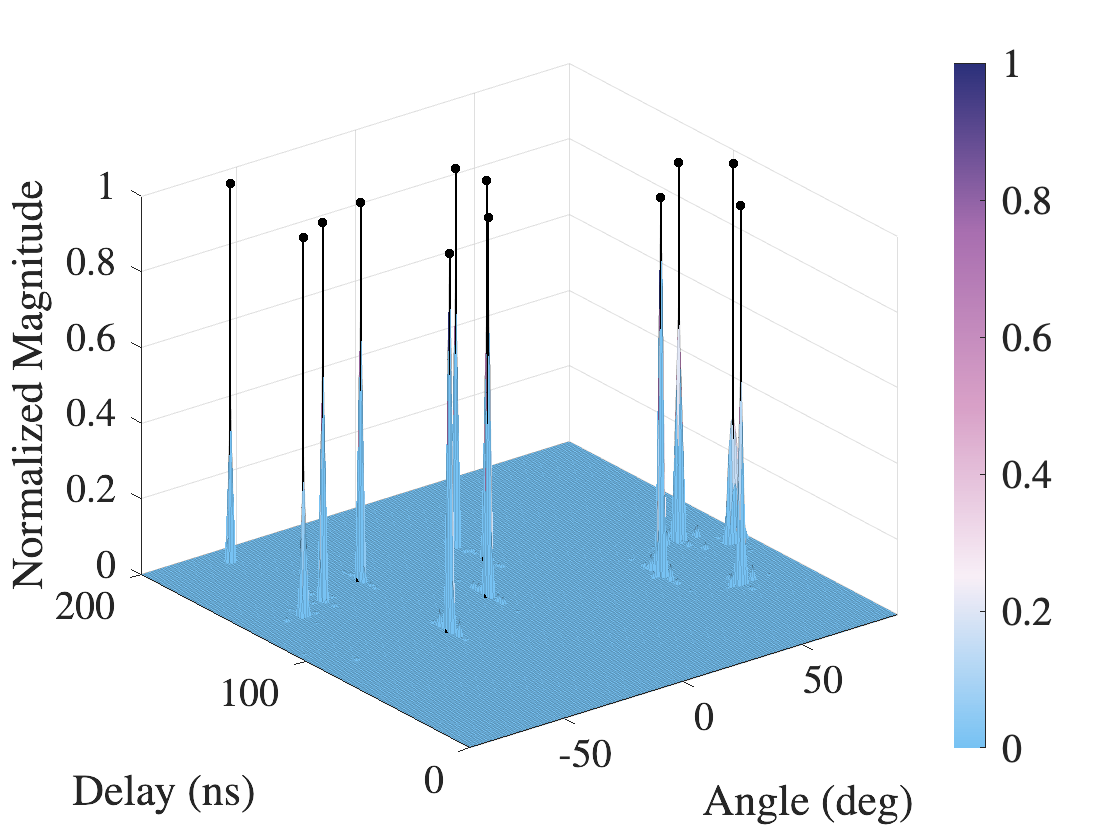

% Diagnostic: Residual convergence
figure
semilogy(reslog(:,1), 'Color', colors(1,:), 'LineWidth', 1); hold on;
semilogy(reslog(:,2), '--', 'Color', colors(1,:), 'LineWidth', 1);
semilogy(reslog(:,3), 'Color', colors(2,:), 'LineWidth', 1);
semilogy(reslog(:,4), '--', 'Color', colors(2,:), 'LineWidth', 1); hold off;
xlabel('Iterations');
ylabel('Residual');
xlim([0 iter]);
title('Residual Convergence');
legend('Primal Residual', 'Primal Tolerance', 'Dual Residual', 'Dual Tolerance');
grid on;
grid minor;

Plot history of adaptive parameters: 

- Primal residuals for each subband

- Epsilon values over iterations

- Rho values over iterations

% Plot adaptive parameter evolution
figure
subplot(3,1,1)
semilogy(pres_history(1:iter,:));
title('Primal Residual Evolution per Subband');
xlabel('Iterations');
ylabel('Primal Residual');
grid on;

subplot(3,1,2)
plot(epsilon_history(1:iter,:));
title('Adaptive Epsilon Evolution');
xlabel('Iterations');
ylabel('Epsilon Value');
grid on;

subplot(3,1,3)
semilogy(rho_history(1:iter,:));
title('Adaptive Rho Evolution');
xlabel('Iterations');
ylabel('Rho Value');
grid on;

% Normalize estimated channel magnitude
Hestmag_norm = Hestmag / max(Hestmag,[],'all');


** 4. Visualization of Sensing Output**

figure
[gridy,gridx] = meshgrid(delaygrid_cs * 1e9,anglegrid_cs);
surf(gridx,gridy,Hestmag_norm,'EdgeAlpha',0.125); hold on;
colormap(matColorMap(colors([2,3,4,5,1],:),8192)); colorbar;
for idx = 1:npaths
    plot3([angles(idx) angles(idx)],[delays(idx) delays(idx)]*1e9,[0 1],'.-k','LineWidth',1,'MarkerSize',15)
end
hold off;
xlabel('Angle (deg)','Interpreter','latex'); xlim([-90 90]);
ylabel('Delay (ns)','Interpreter','latex'); ylim([0 200]);
zlabel('Normalized Magnitude','Interpreter','latex');
formatMyFigure();